%load images and labels
crop_size = 72;
[test, train, test_labels, train_labels] = load_images(crop_size);

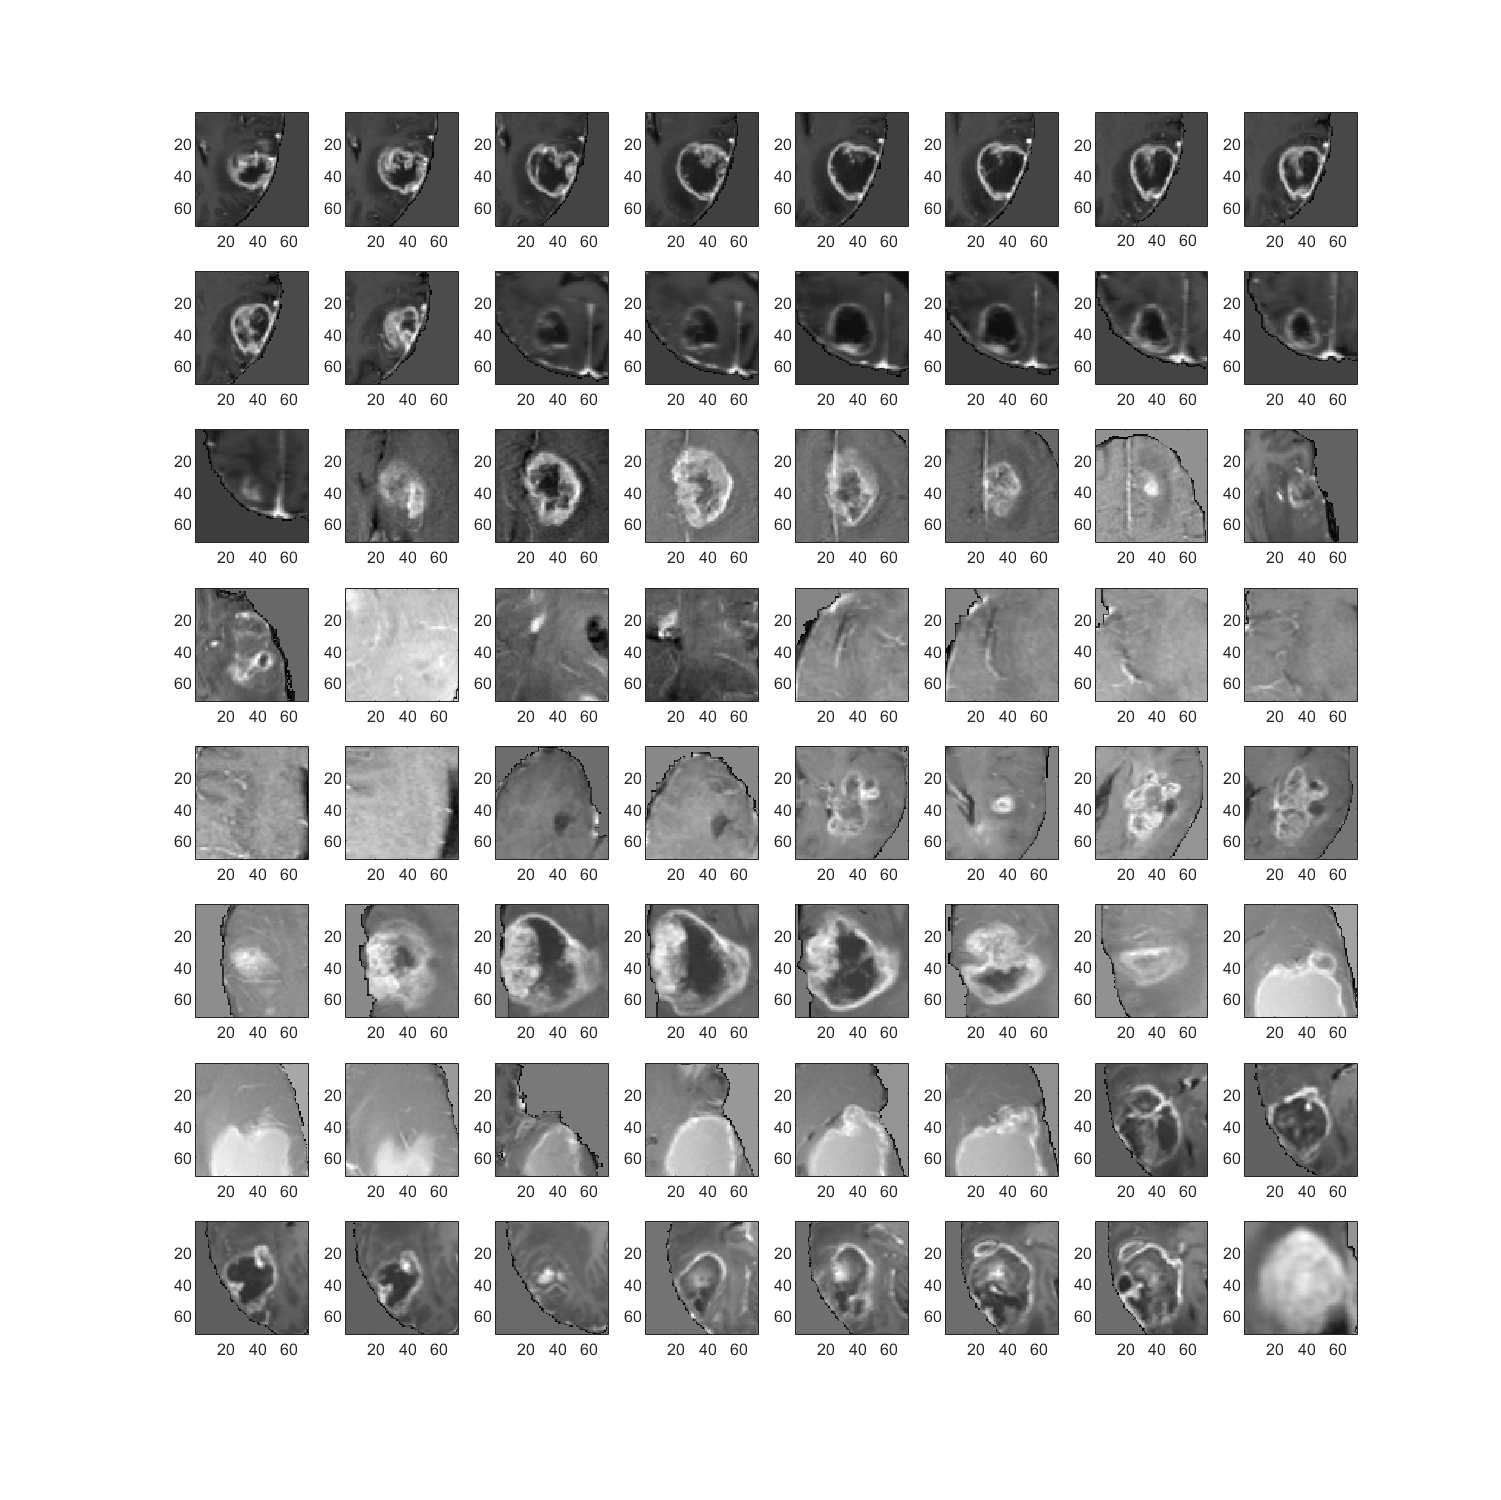

%plot
figure(1)
clf
set(figure(1), "Position", [0 0 1000 1000])
 for i=1:64
     subplot(8,8,i)
     imagesc(reshape(train(i+9,:), crop_size, crop_size))
     axis equal
 end
 colormap 'gray'

%PCA
 train_mc = train - mean(train, 2);
 R = train_mc(8:24, :)' * train_mc(8:24, :);
 [V, D] = eigs(R, 17);

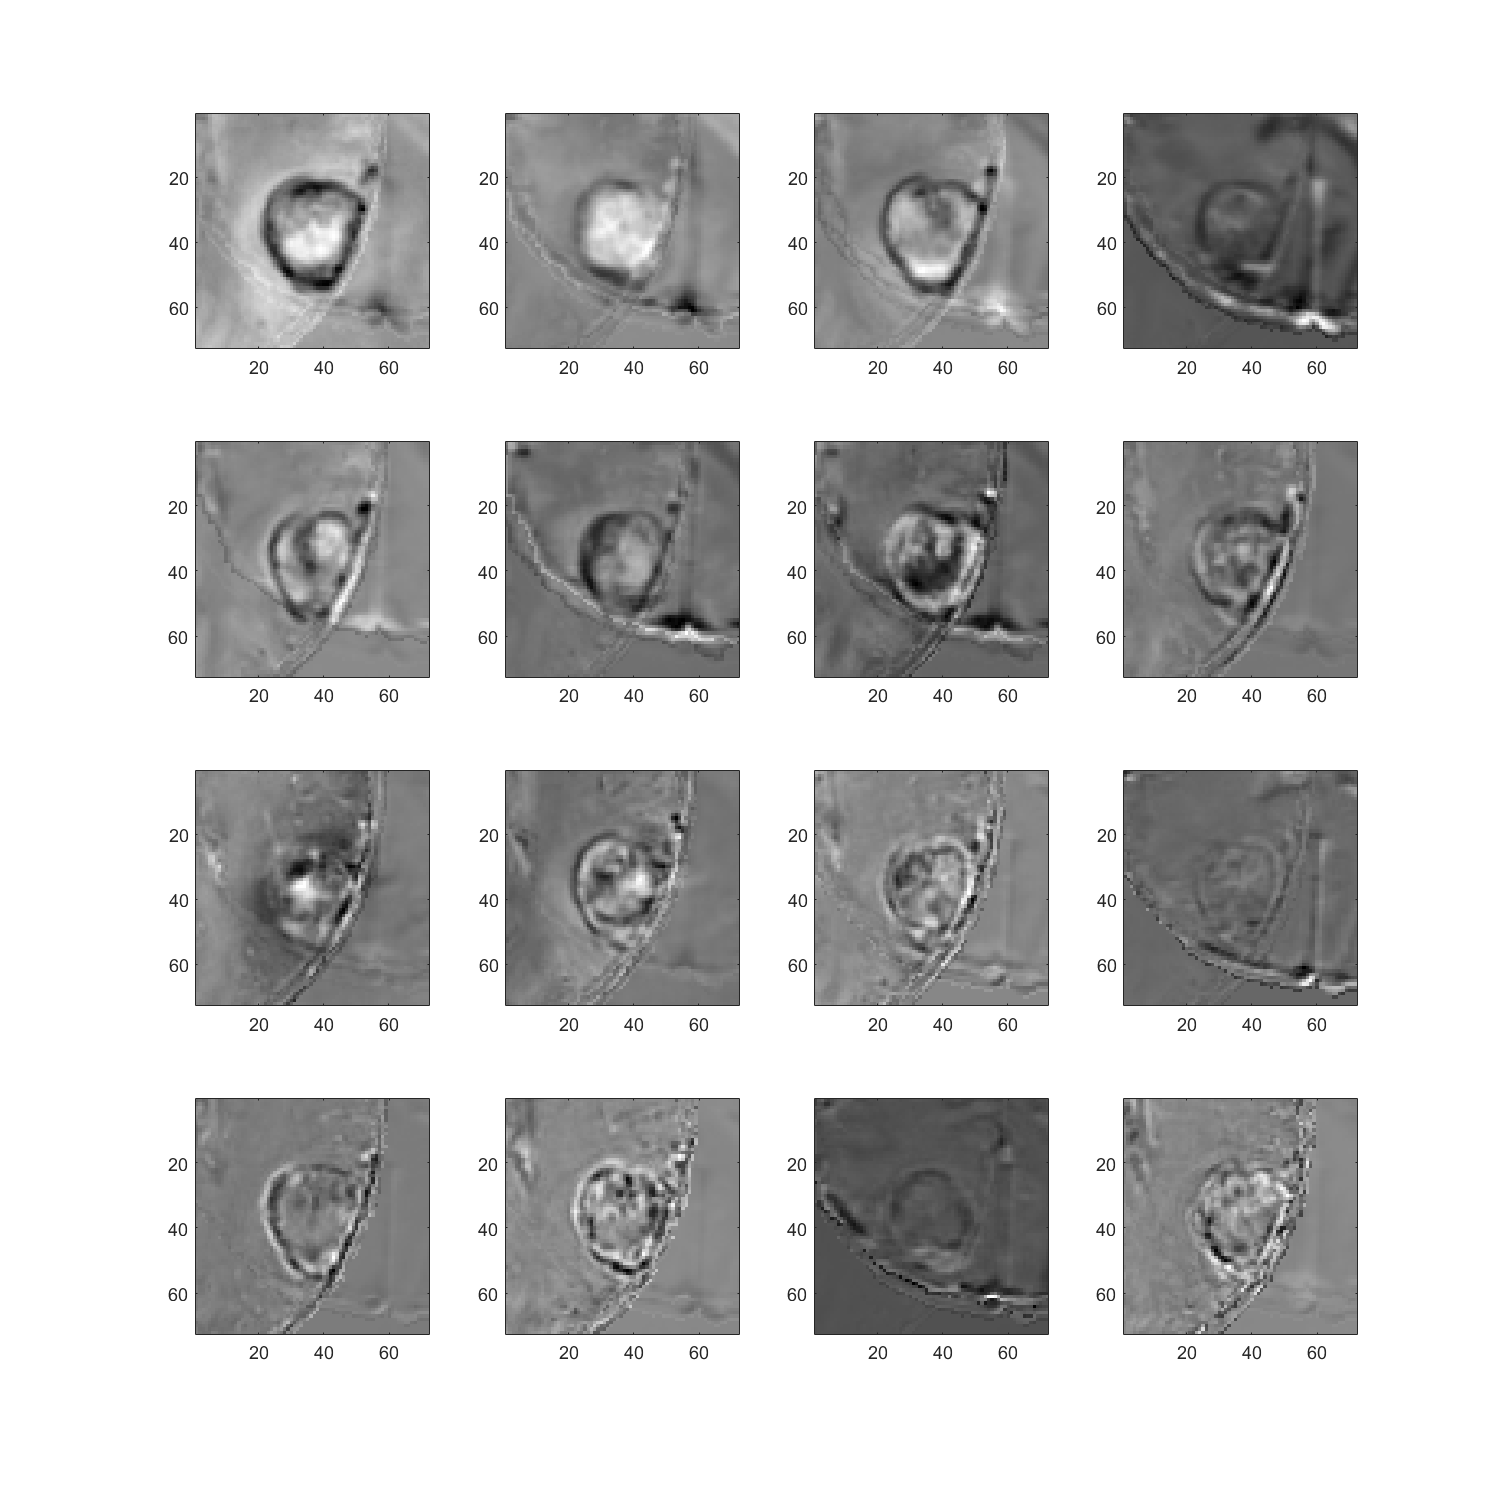

%plot tumor space
 figure(2)
 clf
clf
set(figure(2), "Position", [0 0 1000 1000])
 for i=1:16
     subplot(4,4,i)
     imagesc(reshape(V(:,i), crop_size, crop_size))
     axis equal
 end
 colormap 'gray'

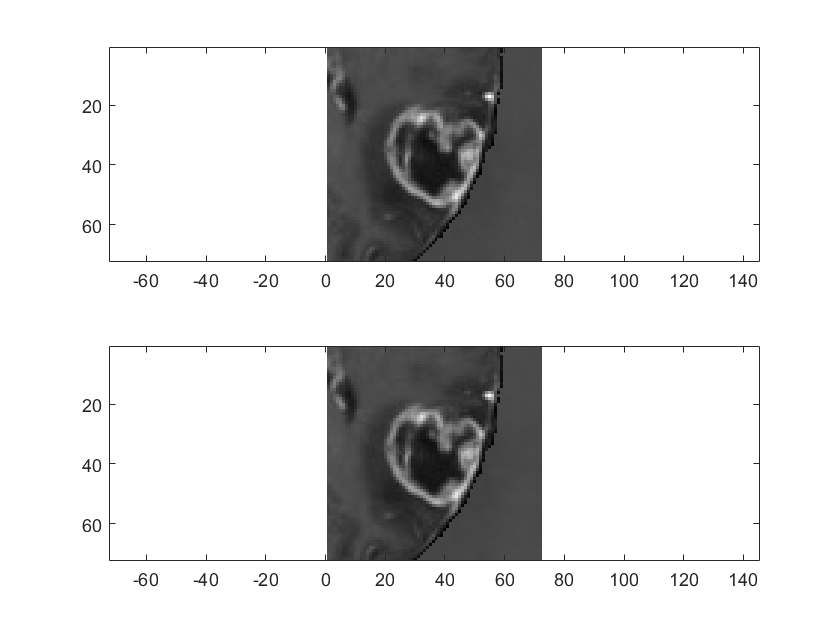


train_comp = train_mc*V;
train_restr = train_comp * V';


i = 12;
figure(3)
clf
subplot(2,1,1)
imagesc(reshape(train_mc(i,:), crop_size, crop_size))
axis equal
subplot(2,1,2)
imagesc(reshape(train_restr(i,:), crop_size, crop_size))
colormap 'gray'
axis equal


norm(train_mc(i,:) - train_restr(i,:))

ans = 1.2171e-11

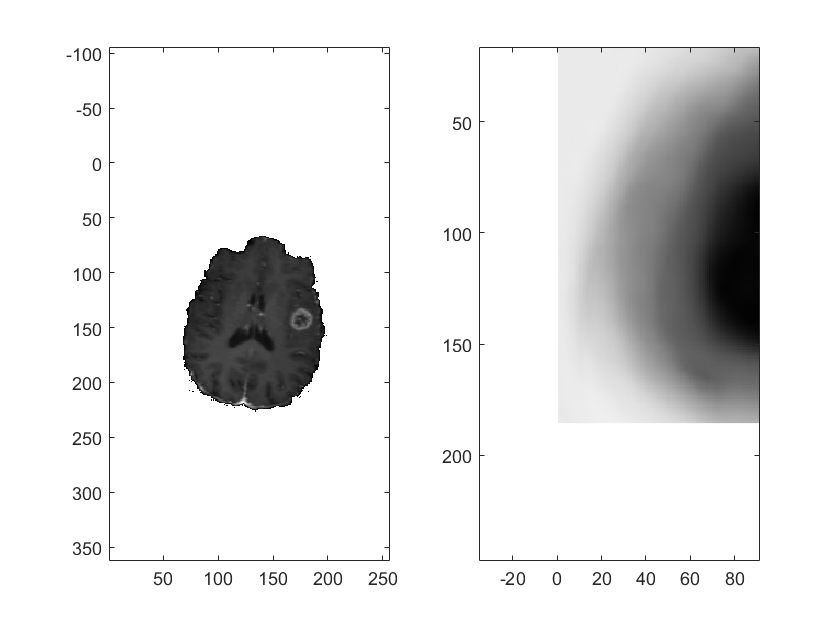


heat_map = zeros(256-crop_size, 256-crop_size);


k = 25;
wholeimage = reshape(test(k,:), 256, 256);


for i=1:256 - crop_size + 1
     for j=1:256 - crop_size + 1



         subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
        
        
         subimage = reshape(subimage, 1, crop_size^2);
         
         si_comp = subimage * V;
         si_restr  = si_comp * V';
         
         epsilon = norm(si_restr - subimage);
         heat_map(i, j) = epsilon;
         
     end
 end
 
 
figure(4)
clf
subplot(1,2,1)
imagesc(wholeimage)
axis equal
subplot(1,2,2)
imagesc(heat_map)
axis equal
colormap 'gray'



[Brightest_Pixel_Value, Max_row, Max_col] = maxpixel(heat_map);

Brightest_Pixel_Value = 1.2605e+04

Max_row = 152

Max_col = 183


x = (Max_col + (crop_size/2)) / 256

x = 0.8555

y = (Max_row + (crop_size/2)) / 256

y = 0.7344


norm(test_labels(k,:) - [x, y])

ans = 0.2500


test_labels(1,:)

ans =     0.6109    0.6614



i = 0;
j = 0;


Gamma = reshape(test(1,:), 256, 256);
Gamma = Gamma(1+i:crop_size+i, 1+j:crop_size+j);
Gamma = reshape(Gamma, [], 1);
Psi = transpose(1 / 288 * sum(train));

c1 = 2 * corr(Gamma, Psi);
c2 = corr(Gamma, V);
c3 = corr(Psi, V);

epsilon = (Gamma'* Gamma) - c1 + (Psi' * Psi) + sum(c2 - c3);

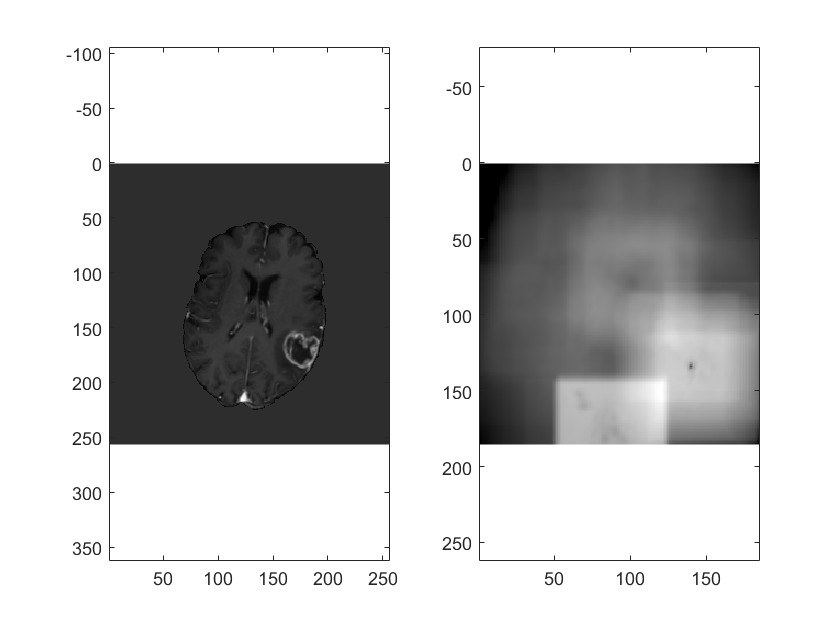


heat_map = zeros(256-crop_size, 256-crop_size);


k = 25;
wholeimage = double(imread("axial_t1wce_2_class\images\train\00097_72.jpg"));
a = reshape(wholeimage, 1, []);
i1 = a < 10;
i2 = a >= 10;
a(i1) = mean(a(i2));

wholeimage = reshape(a, 256, 256);

for i=1:256 - crop_size + 1
     for j=1:256 - crop_size + 1
         


         
         subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
        
        
         subimage = reshape(subimage, 1, crop_size^2);
         
        i1 = subimage < 3;
        i2 = subimage >= 3;
        subimage(i1) = mean(subimage(i2));
         
         subimage = subimage - mean(subimage);
         
         si_comp = subimage * V;
         si_restr  = si_comp * V';
         
         epsilon = norm(si_restr - subimage);
         heat_map(i, j) = epsilon;
         
     end
 end
 
 
figure(5)
clf
subplot(1,2,1)
imagesc(wholeimage)
axis equal
subplot(1,2,2)
imagesc(heat_map)
axis equal
colormap 'gray'



[Brightest_Pixel_Value, Max_row, Max_col] = maxpixel(heat_map);

Brightest_Pixel_Value = 1.6899e+03

Max_row = 152

Max_col = 120


x = (Max_col + (crop_size/2)) / 256

x = 0.6094

y = (Max_row + (crop_size/2)) / 256

y = 0.7344


norm(test_labels(k,:) - [x, y])

ans = 0.1969


test_labels(1,:)

ans =     0.6109    0.6614


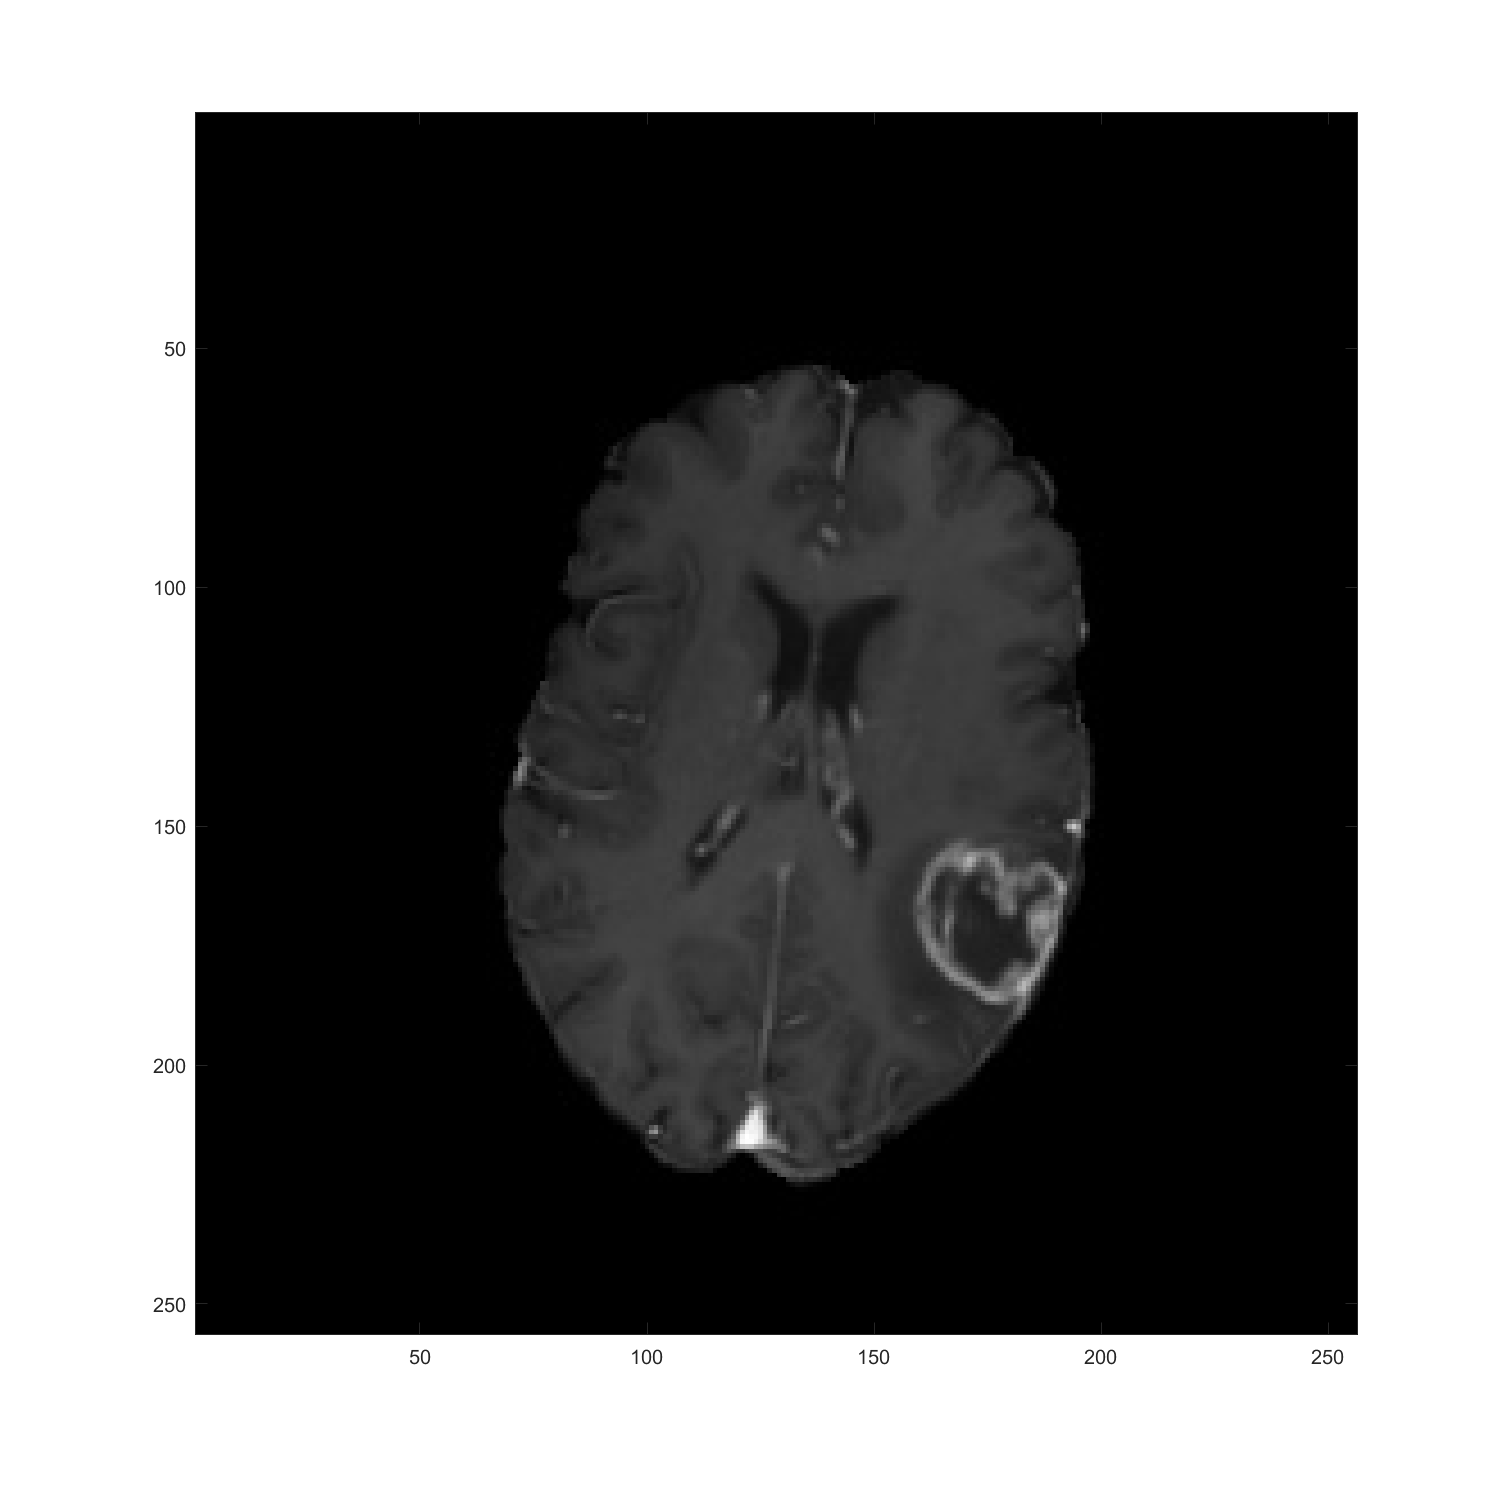

wholeimage = double(imread("axial_t1wce_2_class\images\train\00097_72.jpg"));
clf
imagesc(wholeimage);

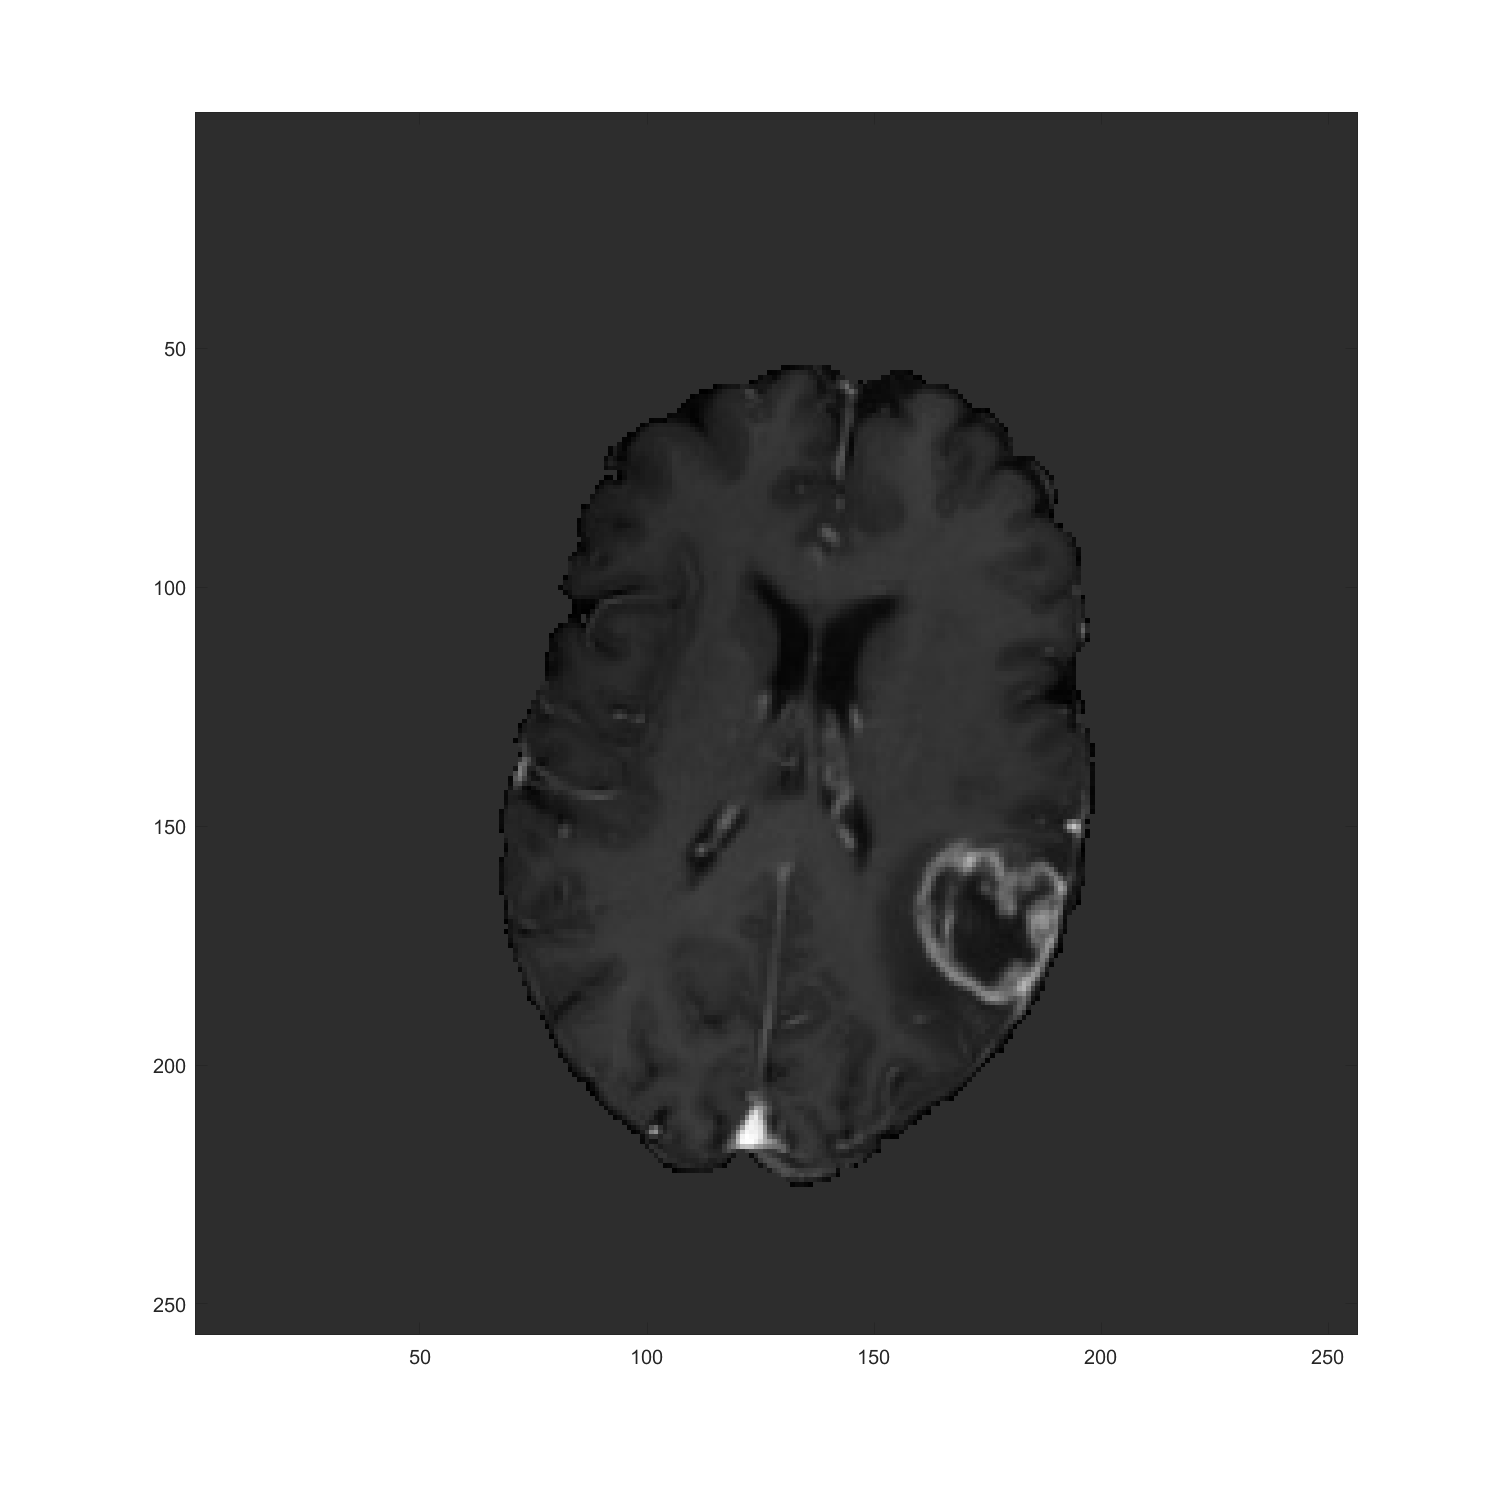

wholeimage = double(imread("axial_t1wce_2_class\images\train\00097_72.jpg"));
a = reshape(wholeimage, 1, []);

i1 = a < 10;
i2 = a >= 10;
a(i1) = mean(a(i2));

wholeimage = reshape(a, 256, 256);

clf
imagesc(wholeimage)

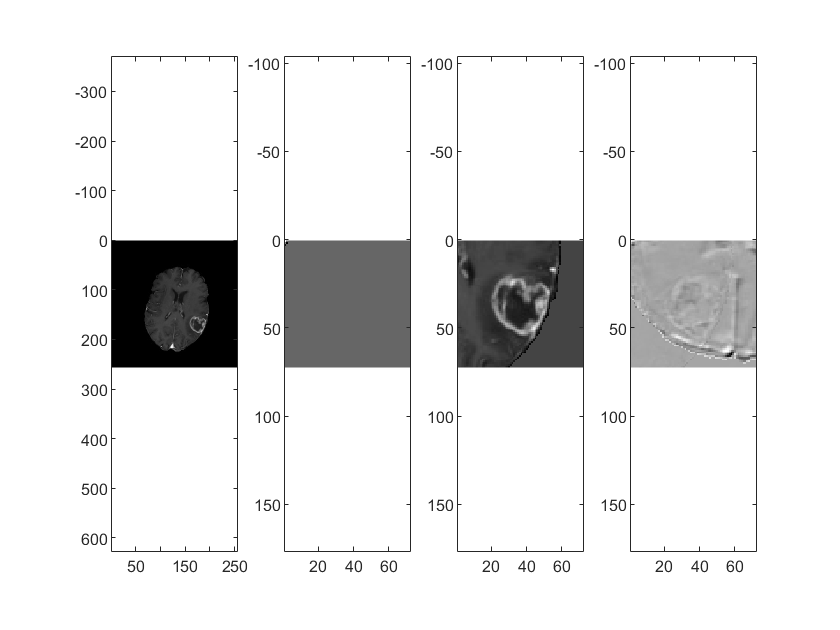

heat_map = zeros(256-crop_size, 256-crop_size);


wholeimage = double(imread("axial_t1wce_2_class\images\train\00097_72.jpg"));


a = reshape(wholeimage, 1, []);
%  i1 = a < 10;
%  i2 = a >= 10;
%  a(i1) = 100;%mean(a(i2));
%a = a - mean(a);
wholeimage = reshape(a, 256, 256);
         
edge_cut = 20;
% i = 134;
% j = 140;

%i = 134;
%j = 140;
 
 for i=1:256 - crop_size + 1
      for j=1:256 - crop_size + 1

         
         subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
         subimage = reshape(subimage, 1, []);
         
          i1 = subimage < 10;
          i2 = subimage >= 10;
          subimage(i1) = mean(subimage(i2));
        
        
           m = mean(subimage);
         subimage = subimage - m;
          
        
         
         
            
         
         
%        
         si_comp = subimage * V;
         si_restr  = si_comp * V';
         
         epsilon = norm(si_restr - subimage);
         if m > edge_cut
             heat_map(i, j) = epsilon;
         else
             heat_map(i, j) = 5000;
         end
         
      end
 end


 
 
figure(8)
clf
subplot(1,4,1)
imagesc(wholeimage)
axis equal
subplot(1,4,2)
imagesc(reshape(subimage, 72, 72))
axis equal
subplot(1,4,3)
imagesc(reshape(train_mc(12,:), crop_size, crop_size))
axis equal
subplot(1,4,4)
imagesc(reshape(si_restr, 72, 72))
axis equal
colormap 'gray'


norm(subimage - train_mc(12,:))

ans = 1.3577e+03

norm(subimage - si_restr)

ans = 24.0650

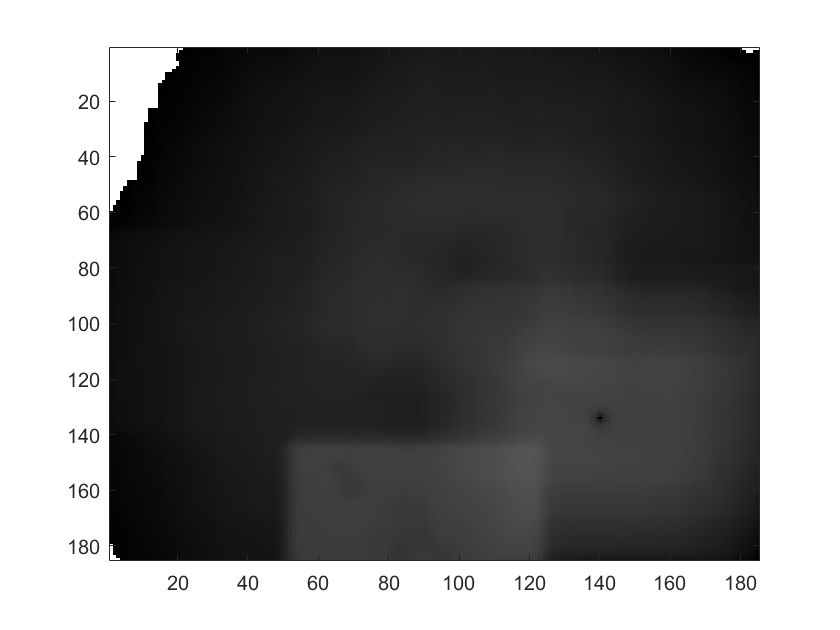



figure(9)
clf
imagesc(heat_map)
colormap 'gray'

[Brightest_Pixel_Value, Max_row, Max_col] = maxpixel(heat_map);

Brightest_Pixel_Value = 0

Max_row =    183
    53
    51
    49
    23
    10
     2
     2


Max_col =      2
     4
     5
     6
    12
    17
   184
   185
